## **Tarea Nº1: **

# **Procesamiento y Reconstrucción de Imágenes Médicas**

#### Universidad Técnica Federico Santa Maria

#### Departamento de Informatica - CSSJ - CC

#### ENUNCIADO

**a) Interpolación Trilineal (20 pts): **La siguiente página de Wikipedia ([https://acortar.link/q9pEiw](https://acortar.link/q9pEiw)), muestra matemáticamente como se puede realizar la Interpolación Trilineal. Desarrolle su propio código en forma de función de MATLAB, que reciba como entrada una imagen 3D, y un factor de escalamiento. Por ejemplo ***“im_out = trilineal_XX_YY(im_in, factor)”***, donde: 

- **XX_YY** = iniciales del nombre y apellido de los/as integrantes del grupo. 

- **im_in** = es el volumen de entrada. 

- **factor** = factor de escalamiento que va entre 0.05 < factor < 2 para este caso. 

El factor de escalamiento quiere decir que cuando factor tenga un valor de 0.5, mi imagen de salida tendrá un 50% del tamaño original, cuando tenga un valor de 2 la imagen de salida debe tener el doble del tamaño de la imagen original.  El código debe funcionar para cualquier rango de valores entre 0.05 y 2.

Genere una sección de “Help” en su función de MATLAB, donde describa brevemente lo que hace su código y adicionalmente debe definir los inputs, outputs, y incluir un ejemplo de ejecución de su código. 

***No se pueden usar las funciones de interpolación de Matlab, debe desarrollar su propio código***.

% Ejemplo de mi implementacion de la Interpolacion Trilinear
vol = rand(50,50,50);
resultado = trilineal_MS_SS(vol, 1.2);

**b) Reconstrucción de imágenes (20pts):** usted dispone de 2 imágenes que se encuentran dañadas con artefactos que son fácilmente visible en su espacio k.

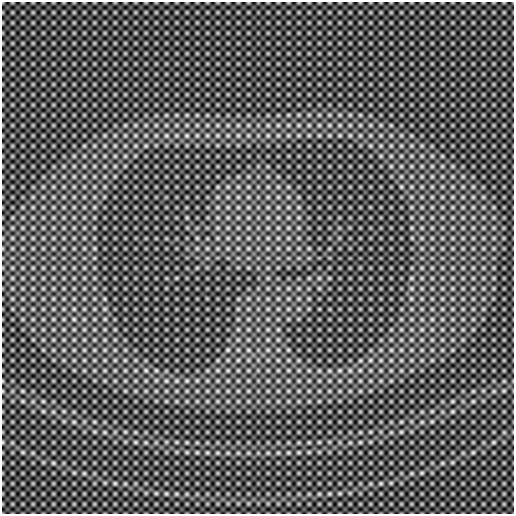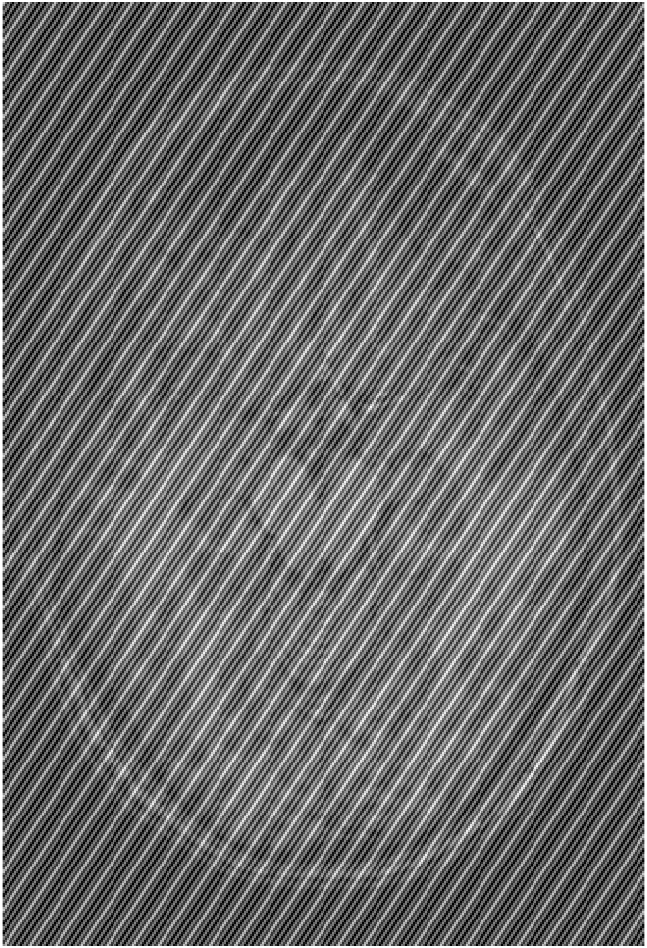

Implemente la estrategia que usted estime conveniente para poder corregir este problema y reconstruir la imagen lo mejor posible. Describa detalladamente que estrategia siguió. ***No está autorizado de usar las funciones de Matlab, ni para corregir la imagen, ni reconstruir la imagen, debe desarrollar su propio código (Usted puede hacer uso de códigos que desarrollamos en clases) ***

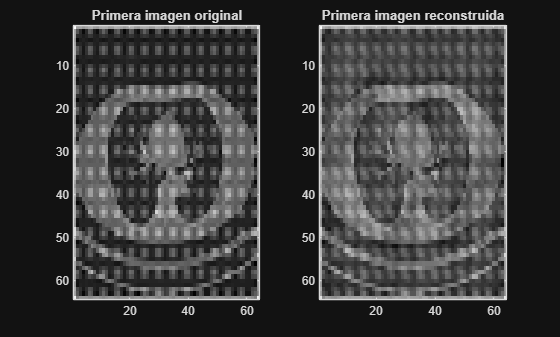

% Carga la primera imagen desde la ruta especificada
imagen_uno = imread('imagenes/t1b1.png');
imagen_dos = imread('imagenes/t1b2.png');

% Luego verifica si las imagenes estan en RGB, ya que en el
% curso acostumbramos a trabajar con imagenes monocromaticas

% Para la imagen uno
if ndims(imagen_uno) == 3
    imagen_uno = double(imagen_uno);
    imagen_uno = 0.2989 * imagen_uno(:,:,1) + ...
        0.5870 * imagen_uno(:,:,2) + ...
        0.1140 * imagen_uno(:,:,3);
else
    imagen_uno = double(imagen_uno);
end

% Para la imagen dos
if ndims(imagen_dos) == 3
    imagen_dos = double(imagen_dos);
    imagen_dos = 0.2989 * imagen_dos(:,:,1) + ...
        0.5870 * imagen_dos(:,:,2) + ...
        0.1140 * imagen_dos(:,:,3);
else
    imagen_dos = double(imagen_dos);
end

% Ejecuta la funcion en la primera y segunda imagen
resultado_uno = reconstruccion_MS_SS(imagen_uno);
resultado_dos = reconstruccion_MS_SS(imagen_dos);

% Crea un grafico para las imagenes originales
% y su posterior recontruccion usando el algoritmo

% Grafico para la primera imagen
figure;
subplot(1,2,1);
imagesc(imagen_uno);
colormap gray;
title('Primera imagen original');

subplot(1,2,2);
imagesc(resultado_uno);
colormap gray;
title('Primera imagen reconstruida');

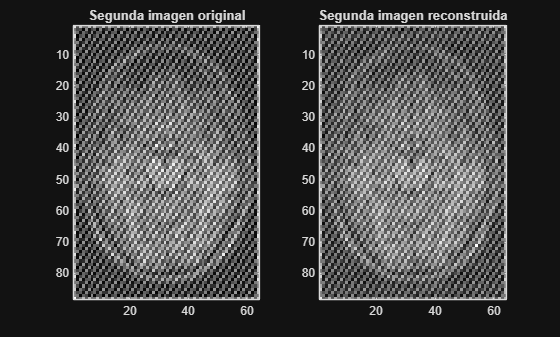

% Grafico para la segunda imagen
figure;
subplot(1,2,1);
imagesc(imagen_dos);
colormap gray;
title('Segunda imagen original');

subplot(1,2,2);
imagesc(resultado_dos);
colormap gray;
title('Segunda imagen reconstruida');

**c) Retroproyección (20 pts):** Usted dispone de los siguientes sinogramas, de dos imágenes desconocidas. 

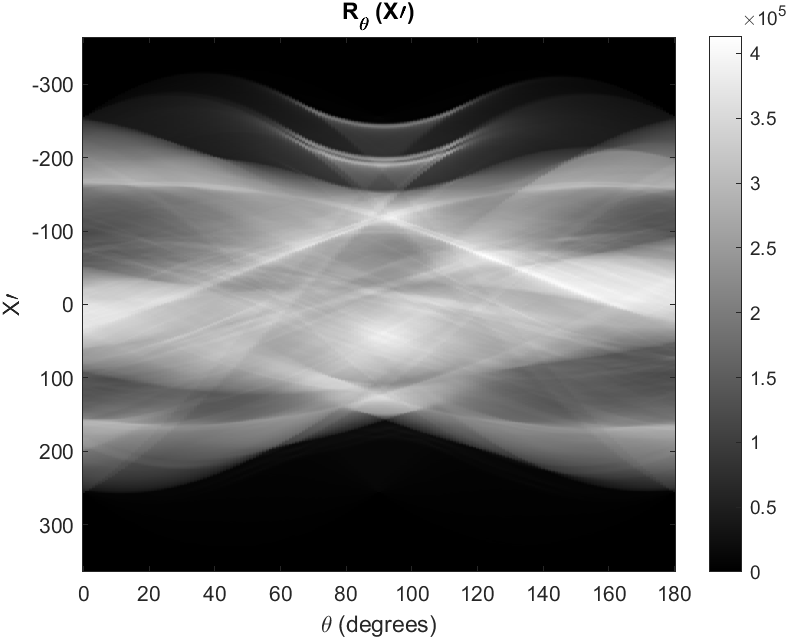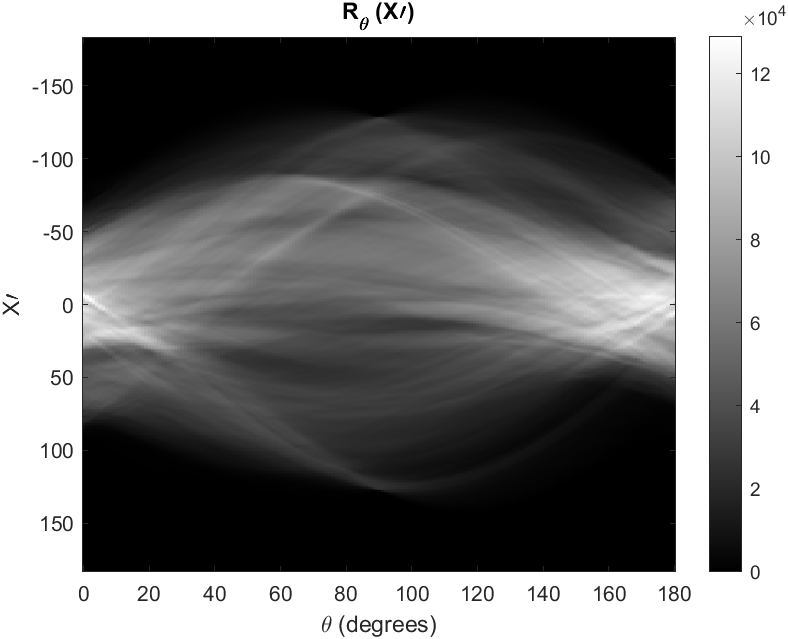

Realice la reconstrucción de la imagen original de cada uno de ellos usando retroproyección con y sin filtrar. Adicionalmente a partir de sus retroproyecciones filtradas, reconstruya la imagen resultante usando la transformada de fourier. ***No se pueden usar las funciones de la transformada de radón o iradon de Matlab, debe desarrollar su propio código. (Si esta permitido usar funciones de rotación en caso de necesitar y las funciones de la transformada de Fourier para filtrar las señales que se usaran posteriormente en cada retroproyección).***

%Escriba su Código aca


**d) Reconstrucción de imágenes paralelas:** A partir de la imagen de cerebro *m.mat *y las sensibilidades de las bobinas entregadas en *C.mat*, genere la imagen obtenida por cada bobina y realice lo siguiente:

**d.1) (5 pts)** Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de suma de cuadrados.  


$$m\left(r\right)=\sqrt{\sum_{i=1}^{N_c } |m_i \left(r\right)|^2 }$$


%Escriba su Código aca

**d.2) (5 pts) **Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de combinación de sensibilidad pesadas. 


$$m\left(r\right)=\frac{\sum_{i=1}^{N_c } c_i^* \left(r\right)m_{i\left(r\right)} }{\sqrt{\sum_{i=1}^{N_c } |c_i \left(r\right)|^2 }}$$


%Escriba su Código aca

**d.3) (10 pts)** Aplique el método de reconstrucción SENSE de imágenes paralelas visto en el código de ejemplo de Matlab para un submuestreo x4, x6, x8. Muestre en pantalla las imágenes de cada una de las bobinas sub-muestreadas y también entregue la imagen reconstruida final. Comente acerca de los resultados obtenidos. 

%Escriba su Código aca


**d.4) (20 pts) **Finalmente investigue acerca del método de reconstrucción GRAPPA (Generalized autocalibrating partially parallel acquisitions), e impleméntelo a cada una de las imágenes de las bobinas con submuestreo x2, y reconstruya la imagen resultante con la ecuación de combinación de sensibilidad pesadas. Puede mirar el paper original de GRAPPA, para orientarse ([https://doi.org/10.1002/mrm.10171](https://doi.org/10.1002/mrm.10171)). 

%Escriba su Código aca